# Trial 1: Asymptotic Efficiency under Repeated Measurement 

clear;
close all;
clc;

## 1. Settings

### 1.1 enviroment settings

%set room size, robot size, and the true pose
Room_Length=50; Room_Width=50;
Robot_Size=3;
theta=60; R=[cosd(theta),-sind(theta);sind(theta),cosd(theta)];
t=[0;25];

### 1.2 simulation settings

T=[1,10,100,1000,10000]; %number T of repeated ranging
sigma=0.05*[1,2,3,4,5,6];%Standard Deviations
L=100;                   %Monte-Carlo rounds
%matrix to store simulation results
%ULS
Y0_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t
%GN-ULS
Ye_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t
%MultiGN-ULS
Ym_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t
%GN-SDP
Y1_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t
%GTRS
Y2_r=zeros(length(T),3);   %RMSE: chordal distance, angular distance, t
%Lower Bound
CRLB=zeros(length(T),2);

%vector to store computation time
time_0=zeros(length(T),1);
time_e=zeros(length(T),1);
time_m=zeros(length(T),1);
time_1=zeros(length(T),1);
time_2=zeros(length(T),1);


## 2. For different number T of repeated ranging

for o=1:length(T)
    M=3; % M*T(o) anchors
    N=2; % N tags
    [A,S,Mt]=setting(T(o),Room_Length,Room_Width,Robot_Size,M,N);

    %mse
    mse_R0_c=0; mse_R0_a=0; mse_t0=0;
    mse_Re_c=0; mse_Re_a=0; mse_te=0;
    mse_Rm_c=0; mse_Rm_a=0; mse_tm=0;
    mse_R1_c=0; mse_R1_a=0; mse_t1=0;
    mse_R2_c=0; mse_R2_a=0; mse_t2=0;

    %true distance
    Sa=R*S+t; %tags' coordinate in global frame
    relative_position=zeros(2,Mt*N);
    for i=1:N %for every tag i=1,...,N
        relative_position(:,(i-1)*Mt+1:i*Mt)=A-Sa(:,i);
    end
    relative_distance=vecnorm(relative_position)'; %(Mt*N,1)

#### CRLB

    Sigma=zeros(1,Mt*N); %standard deviations
    for i=1:N
        Sigma((i-1)*Mt+1:i*Mt)=repmat(sigma((i-1)*M+1:i*M),1,T(o));
    end
    F=zeros(6,6);   %Fisher information
    for i=1:N       %for every tag i=1,...,N
        s_bar=[S(:,i);1];
        for m=1:Mt
            score=kron(s_bar,eye(2))*relative_position(:,(i-1)*Mt+m)/Sigma((i-1)*Mt+m)/relative_distance((i-1)*Mt+m);
            F=F+score*score';
        end
    end

#### ULS- precalculation    

    tic
    A_bar=A-(A*ones(Mt,1))*ones(1,Mt)/Mt;
    Psi=[0,1;1,0;-1,0;0,1];%(4,2)
    H1=-2*kron(S',A_bar')*Psi;    %(N*Mt,2)
    H2=repmat(-2*A_bar',N,1); %(N*Mt,2)
    H=[H1,H2];       %(N*Mt,4)
    HtH_invHt=(H'*H)\H';
    time_0(o)=time_0(o)+toc;

#### SDP- precalculation    

    tic
    c_norm = repmat((vecnorm(S))',Mt,1); %(Mt*N,1),||c||
    C=zeros(Mt*N,1);
    for i=1:N
        C((i-1)*Mt+1:i*Mt,:)=c_norm(i).^2;
    end
    time_1(o)=time_1(o)+toc;

#### **GTRS-precalculation**

    tic
    E1=zeros(Mt*N,2);
    E2=zeros(Mt*N,2);
    for i=1:N
        sigma_Mt=Sigma((i-1)*Mt+1:i*Mt); %standard deviation for range measurements of tag i
        %projection
        TAt= A'-ones(Mt,1)*((1./sigma_Mt.^2)*A')/(sum(1./sigma_Mt.^2));
        E1((i-1)*Mt+1:i*Mt,:)=-2*(kron(S(:,i)',TAt))*Psi; 
        E2((i-1)*Mt+1:i*Mt,:)=-2*TAt; 
    end
    time_2(o)=time_2(o)+toc;

### 2.1 Monte-Carlo Runs 

    for l=1:L
        d=relative_distance+Sigma'.*randn(Mt*N,1); %(Mt*N,1) distance measurements corrupted by Gaussian noises
        d_square=d.^2;

        %ULS
        tic;
        D=d_square-(vecnorm(repmat(A,1,N))').^2-(Sigma').^2;
        %projection
        for i=1:N
            D_bar((i-1)*Mt+1:i*Mt,:)= D((i-1)*Mt+1:i*Mt,:)-ones(Mt,1)*(ones(1,Mt)*D((i-1)*Mt+1:i*Mt,:))/Mt;
        end
        [R0,t0]= ULS(D_bar,HtH_invHt);
        time_0(o)=time_0(o)+toc/L;

        %GN-ULS
        tic;
        [Re,te] = Gauss_Newton(R0,t0,A,S,d,Sigma);
        time_e(o)=time_e(o)+toc/L;

        %multiGN-ULS
        tic;
        Rm=Re;
        tm=te;
        for k=1:10
            [Rm,tm]=Gauss_Newton(Rm,tm,A,S,d,Sigma);
        end
        time_m(o)=time_m(o)+toc/L;

        %GN-SDP
        tic;
        d1=d_square-(vecnorm(repmat(A,1,N))').^2-C;%(Mt*N,1)
        %       Rn=4*(d.*Sigma').^2+2*(Sigma').^4;
        Rn=4*(d.*Sigma').^2;  %ignore chi-squared random variable
        [R1,t1]= SDP(A,S,d1,Rn);
        [R1,t1]=Gauss_Newton(R1,t1,A,S,d,Sigma);
        time_1(o)=time_1(o)+toc/L;

        %GTRS-first step
        tic
        DD=d_square-(vecnorm(repmat(A,1,N))').^2; %ignore the chi-squared random variable
        %projection
        for i=1:N
            sigma_Mt=Sigma((i-1)*Mt+1:i*Mt); %standard deviation for range measurements of tag i
            DD_bar((i-1)*Mt+1:i*Mt,:)=DD((i-1)*Mt+1:i*Mt,:)-ones(Mt,1)*( ((1./(sigma_Mt.^2))*DD((i-1)*Mt+1:i*Mt,:))/(sum(1./(sigma_Mt.^2))) );
        end

        [y20,t20]=GTRS(E1,E2,Rn,DD_bar,Mt,N);
        R20=[y20(2),-y20(1);y20(1),y20(2)];
        %GTRS-second step
        DDD=zeros(Mt*N,1);
        F1=zeros(Mt*N,2);
        F2=zeros(Mt*N,2);
        for i=1:N
            DDD((i-1)*Mt+1:i*Mt,:)=d_square((i-1)*Mt+1:i*Mt,:)-vecnorm(t20-A)'.^2-norm(S(:,i)).^2;
            F1((i-1)*Mt+1:i*Mt,:)=2*kron(S(:,i)',(t20-A)')*Psi;
            F2((i-1)*Mt+1:i*Mt,:)=2*(repmat(R20*S(:,i)+t20,1,Mt)'-A');
        end
        [y2,dt2]=GTRS(F1,F2,Rn,DDD,Mt,N);
        R2=[y2(2),-y2(1);y2(1),y2(2)];
        t2=t20+dt2;
        time_2(o)=time_2(o)+toc/L;

        %MSE
        %ULS
        mse_R0_c=mse_R0_c+norm(R0-R,'fro')^2;
        mse_R0_a=mse_R0_a+angular_distance(R0,R)^2;
        mse_t0=mse_t0+norm(t0-t)^2;
        %GN-UCLS
        mse_Re_c=mse_Re_c+norm(Re-R,'fro')^2;
        mse_Re_a=mse_Re_a+angular_distance(Re,R)^2;
        mse_te=mse_te+norm(te-t)^2;
        %multiGN-ULS
        mse_Rm_c=mse_Rm_c+norm(Rm-R,'fro')^2;
        mse_Rm_a=mse_Rm_a+angular_distance(Rm,R)^2;
        mse_tm=mse_tm+norm(tm-t)^2;
        %GN-SDP
        mse_R1_c=mse_R1_c+norm(R1-R,'fro')^2;
        mse_R1_a=mse_R1_a+angular_distance(R1,R)^2;
        mse_t1=mse_t1+norm(t1-t)^2;
        %GTRS
        mse_R2_c=mse_R2_c+norm(R2-R,'fro')^2;
        mse_R2_a=mse_R2_a+angular_distance(R2,R)^2;
        mse_t2=mse_t2+norm(t2-t)^2;
        if mode(l,10)==0 %iteration tracking
            l
        end
    end
    time_e(o)=time_e(o)+time_0(o);
    time_m(o)=time_m(o)+time_e(o);

### 2.2 RMSE

    %ULS
    Y0_r(o,1)=sqrt(mse_R0_c/L);
    Y0_r(o,2)=sqrt(mse_R0_a/L);
    Y0_r(o,3)=sqrt(mse_t0/L);
    %GN-ULS
    Ye_r(o,1)=sqrt(mse_Re_c/L);
    Ye_r(o,2)=sqrt(mse_Re_a/L);
    Ye_r(o,3)=sqrt(mse_te/L);
    %multiGN-ULS
    Ym_r(o,1)=sqrt(mse_Rm_c/L);
    Ym_r(o,2)=sqrt(mse_Rm_a/L);
    Ym_r(o,3)=sqrt(mse_tm/L);
    %GN-SDP
    Y1_r(o,1)=sqrt(mse_R1_c/L);
    Y1_r(o,2)=sqrt(mse_R1_a/L);
    Y1_r(o,3)=sqrt(mse_t1/L);
    %GTRS
    Y2_r(o,1)=sqrt(mse_R2_c/L);
    Y2_r(o,2)=sqrt(mse_R2_a/L);
    Y2_r(o,3)=sqrt(mse_t2/L);

### 2.3 Constrained Cramer Rao Lower Bound

    CR=constrained_CRB(F,R);
    CRLB(o,1)=sqrt(sum(diag(CR(1:4,1:4))));
    CRLB(o,2)=sqrt(sum(diag(CR(5:6,5:6))));
    o
end

o = 1

o = 2

o = 3

o = 4

o = 5

% save('Trial1_plot.mat','T','Y0_r','Ye_r','Ym_r','Y1_r','Y2_r','CRLB','time_0','time_e','time_m','time_1','time_2')

## 3. Plot

### 3.1 RMSE and number T of repeated ranging

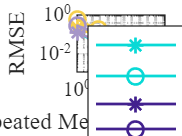

figure(1)
%CRLB
loglog(T,CRLB(:,1),'-*','LineWidth',1,'MarkerSize',6,'Color','#08D9D6');
hold on
loglog(T,CRLB(:,2),'-o','LineWidth',1,'MarkerSize',6,'Color','#08D9D6');
hold on
%GN-SDP
loglog(T,Y1_r(:,1),'-*','LineWidth',1,'MarkerSize',6,'Color','#42218E');
hold on
loglog(T,Y1_r(:,3),'-o','LineWidth',1,'MarkerSize',6,'Color','#42218E');
hold on
%GTRS
loglog(T,Y2_r(:,1),'-*','LineWidth',1,'MarkerSize',6,'Color','#629460');
hold on
loglog(T,Y2_r(:,3),'-o','LineWidth',1,'MarkerSize',6,'Color','#629460');
hold on
%ULS
loglog(T,Y0_r(:,1),'-.*','LineWidth',1,'MarkerSize',6,'Color','#f6d04d');
hold on
loglog(T,Y0_r(:,3),'-.o','LineWidth',1,'MarkerSize',6,'Color','#f6d04d');
hold on
%GN-ULS
loglog(T,Ye_r(:,1),'--*','LineWidth',1,'MarkerSize',6,'Color','#fd5f00');
hold on
loglog(T,Ye_r(:,3),'--o','LineWidth',1,'MarkerSize',6,'Color','#fd5f00');
hold on
%multiGN-UCLS
loglog(T,Ym_r(:,1),'--*','LineWidth',1,'MarkerSize',6,'Color','#a696c8');
hold on
loglog(T,Ym_r(:,3),'--o','LineWidth',1,'MarkerSize',6,'Color','#a696c8');
hold off

set(gca,'Fontname', 'Times New Roman')
xlabel('Repeated Measurement Numbers')
ylabel('RMSE')
legend({'$$\sqrt{CRLB(R)}$$','$$\sqrt{CRLB(t)}$$','GN-SDP(R)','GN-SDP(t)','GTRS(R)','GTRS(t)', ...
    'ULS(R)','ULS(t)','GN-ULS(R)','GN-ULS(t)','multiGN-ULS(R)','multiGN-ULS(t)'}, ...
    'interpreter','latex','Location','southwest')
grid on

### 3.2 computation time for different methods

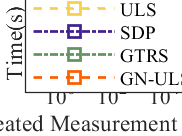

figure(2)
%ULS
semilogx(T,time_0,'--s','LineWidth',1,'MarkerSize',6,'Color','#f6d04d');
hold on
%GN-SDP
semilogx(T,time_1,'-.s','LineWidth',1,'MarkerSize',6,'Color','#42218E');
hold on
%GTRS
semilogx(T,time_2,'-.s','LineWidth',1,'MarkerSize',6,'Color','#629460');
hold on
%GN-ULS
semilogx(T,time_e,'--s','LineWidth',1,'MarkerSize',6,'Color','#fd5f00');
hold on
set(gca,'Fontname', 'Times New Roman')
xlabel('Repeated Measurement Numbers')
ylabel('Time(s)')
legend( 'ULS','SDP','GTRS','GN-ULS','Location','Best')
grid on

% save('Trial1_plot.mat','T','Y0_r','Ye_r','Ym_r','Y1_r','Y2_r','CRLB','time_0','time_e','time_m','time_1','time_2')